# **Generation of a linear triangular mesh using the mesh2d library**

function mshT1 = generateLinearTriangularMeshOnRectangleMesh2d(X0, XLx, Y0, YLy, hfun)

## Function description

Returns a linear triangular mesh for the following rectangular geometry using the Community Toolbox [mesh2d](https://www.mathworks.com/matlabcentral/fileexchange/25555-mesh2d-delaunay-based-unstructured-mesh-generation).

#### 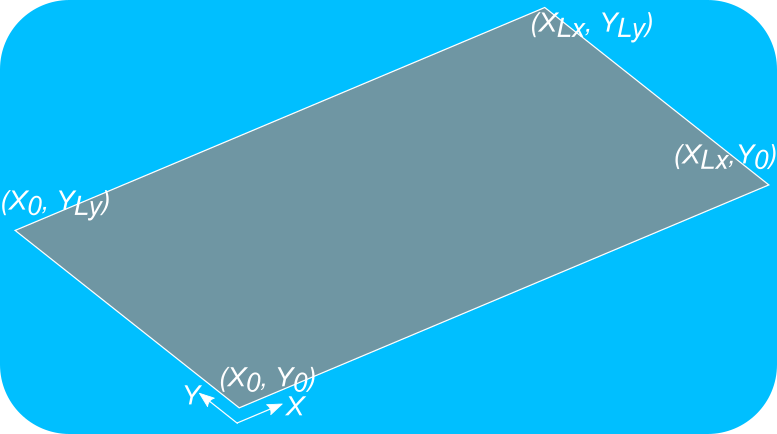

The only property that needs to be defined is the desirable minimum element edge size in input parameter `propMsh.hfun`. Moreover, the path to the installed Community Toolbox [mesh2d](https://www.mathworks.com/matlabcentral/fileexchange/25555-mesh2d-delaunay-based-unstructured-mesh-generation) should be provided in variable `pathToMesh2dLib` in the body of the code below. If the Community Toolbox is not detected, then an empty array for variable `mshT1` is returned.

**                   Input :**

              `X0, XLx` : The $X$-coordinates of the edges of the rectangular plate

              Y`0, YLy` : The $Y$-coordinates of the edges of the rectangular plate

                  `.hfun` : Desirable minimum edge size in the mesh

**               Output :**

                 `mshT1` : MATLAB-struct containing the nodes and elements in the generated linear triangular mesh. If the Community Toolbox cannot be detected, then this is returned as an empty array.

                                        .nodes : Array `[numNodes, 3]` containing the nodes in the linear triangular mesh

                                 `.elements` : Array `[numEl, 3]` containing the node connectivity by means of the node numbering for each element in the linear triangular mesh

## **Function implementation**

### Verify whether library mesh2d from File Exchange is provided

Provide path to [mesh2d](https://www.mathworks.com/matlabcentral/fileexchange/25555-mesh2d-delaunay-based-unstructured-mesh-generation) library that can be found on File Exchange, see [1]

    pathToMesh2dLib = "C:\projects\mesh2d";
    isMesh2DProvided = false;
    existPath = exist(pathToMesh2dLib, 'dir');
    if existPath == 7
        pathToReadmeFile = fullfile(pathToMesh2dLib, "README.md");
        existReadme = exist(pathToReadmeFile, 'file');
        if existReadme == 2
            text = fileread(pathToReadmeFile);
            is_mesh2d_github_link_found = contains(text, ...
                "https://github.com/dengwirda/mesh2d", 'IgnoreCase', true);
            if is_mesh2d_github_link_found
                isMesh2DProvided = true;
            end
        end
    end
    if ~isMesh2DProvided
        disp("Library mesh2d is not provided. Therefore, no triangular " + ...
            "mesh can be generated")
    else
        disp("Path" + pathToMesh2dLib + "is valid")
    end
    if isMesh2DProvided
        addpath(fullfile(pathToMesh2dLib));
        addpath(fullfile(pathToMesh2dLib, "aabb-tree"));
        addpath(fullfile(pathToMesh2dLib, "geom-util"));
        addpath(fullfile(pathToMesh2dLib, "hfun-util"));
        addpath(fullfile(pathToMesh2dLib, "hjac-util"));
        addpath(fullfile(pathToMesh2dLib, "mesh-ball"));
        addpath(fullfile(pathToMesh2dLib, "mesh-cost"));
        addpath(fullfile(pathToMesh2dLib, "mesh-file"));
        addpath(fullfile(pathToMesh2dLib, "mesh-util"));
        addpath(fullfile(pathToMesh2dLib, "poly-test"));
    end

### **Mesh generation**

    vrtcs = [X0     Y0
             X0+XLx Y0
             X0+XLx Y0+YLy
             X0     Y0+YLy];
    edge = zeros(height(vrtcs), 2);
    for ii = 1:height(vrtcs)
        if ii ~= height(vrtcs)
            edge(ii, :) = [ii ii + 1];
        else
            edge(ii, :) = [ii 1];
        end
    end
    try
        [vert, ~, tria, ~] = refine2(vrtcs, edge, [], [], hfun);
        numNodesT1 = height(vert);
        mshT1.nodes = horzcat(vert, zeros(numNodesT1, 1));
        mshT1.elements = tria;
    catch ME
        if isequal(ME.identifier, "MATLAB:UndefinedFunction")
            warning(ME.message)
            mshT1 = [];
        end
    end

end